# **Problem 2:**

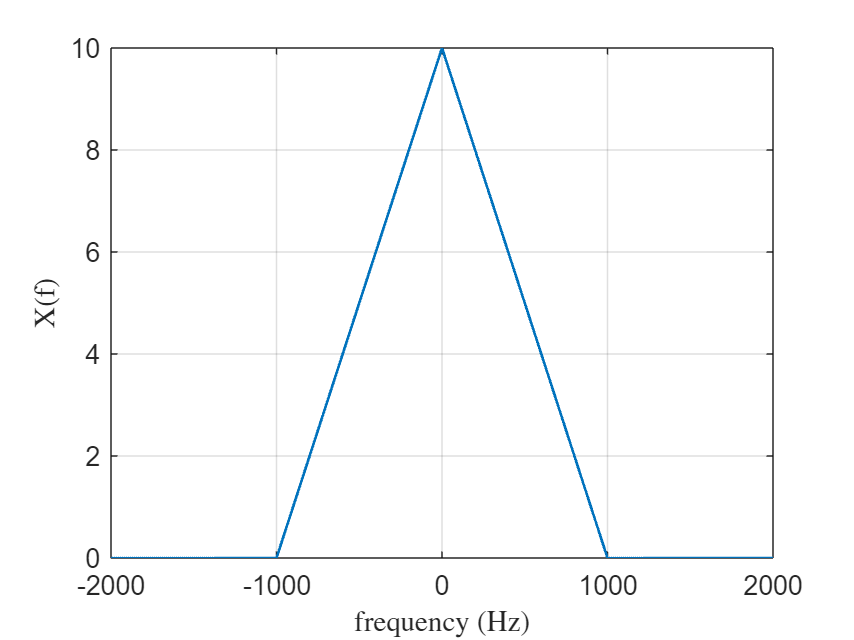

clc;
clear all;
format long;
df=0.01;
f = -2000:df:2000;
Xf = arrayfun(@XX, f);
figure(1)
plot (f, Xf,'LineWidth',1);
ylabel('X(f)','FontWeight','bold','Interpreter','latex');
xlabel('frequency (Hz)','FontWeight','bold','Interpreter','latex');
grid on;

## **Problem 2_a:**

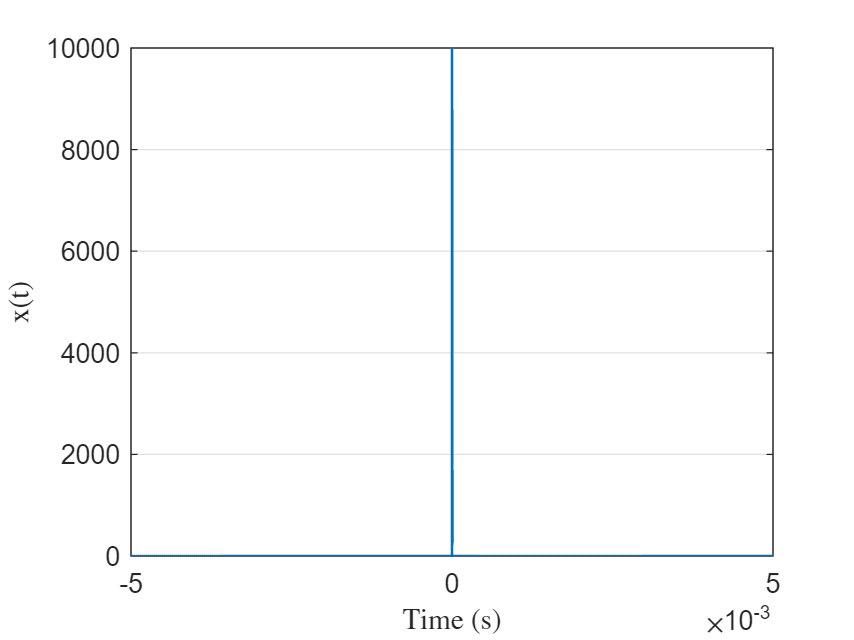

Xf_shifted = ifftshift(Xf);
x_t = fftshift(ifft(Xf_shifted));
N = length(f);
t=linspace(-5e-3,5e-3,N);
x_t = x_t * N *df;
figure(2)
plot(t, x_t ,'LineWidth',1);
ylabel('x(t)','FontWeight','bold','Interpreter','latex');
xlabel('Time (s)','FontWeight','bold','Interpreter','latex');
grid on;

## **Problem 2_b:**

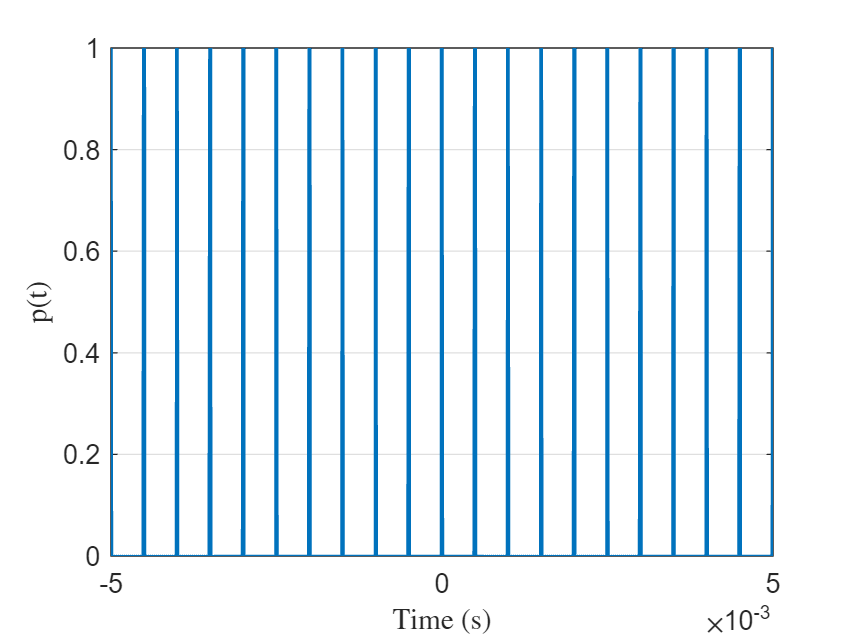

p_t=pp(t);
p_t = arrayfun(@pp, t);
figure(3)
plot(t, p_t ,'LineWidth',1);
xlabel('Time (s)','Interpreter','latex');
ylabel('p(t)','Interpreter','latex');
grid on;

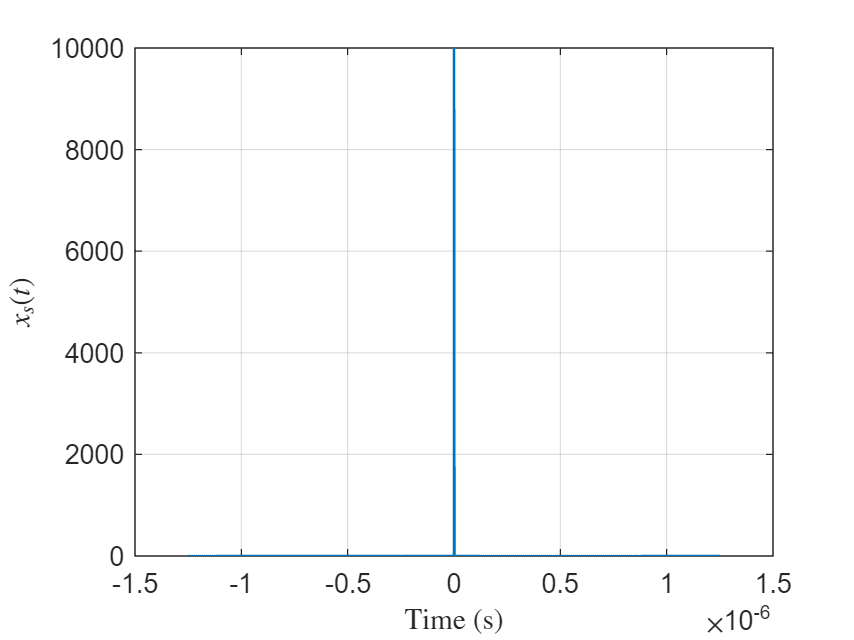


x_s= x_t.*p_t;
figure(4)
plot(t/(N*df), x_s ,'LineWidth',1);
xlabel('Time (s)','Interpreter','latex');
ylabel('$x_s(t)$','Interpreter','latex');
grid on;

## **Problem 2_c:**

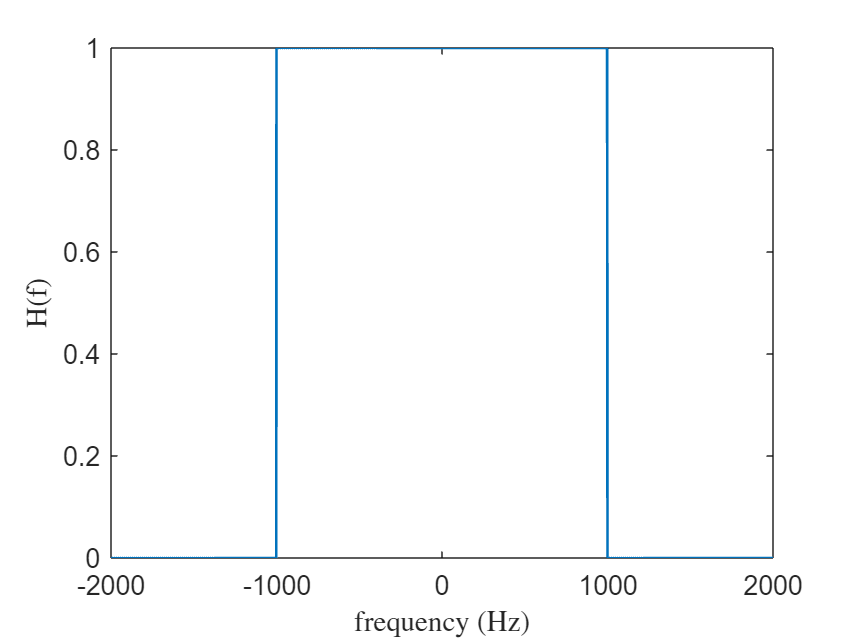

Hf = arrayfun(@H, f);
figure(5)
plot (f, Hf,'LineWidth',1);
ylabel('H(f)','FontWeight','bold','Interpreter','latex');
xlabel('frequency (Hz)','FontWeight','bold','Interpreter','latex');

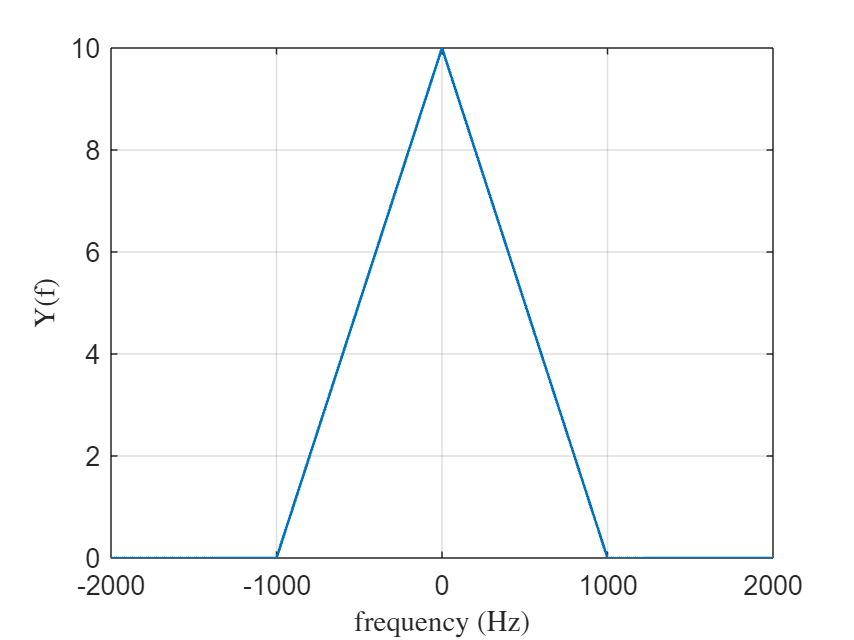

M=length (x_s);
X_s = fft(x_s);
X_s = fftshift(X_s);
X_s = X_s /(M*df);
Y_f = abs(X_s .* Hf);
figure(6)
plot (f, Y_f,'LineWidth',1);
ylabel('Y(f)','FontWeight','bold','Interpreter','latex');
xlabel('frequency (Hz)','FontWeight','bold','Interpreter','latex');
grid on;

function X_f = XX(ff)
    if (abs(ff) < 1000)
        X_f = 10-0.01*abs(ff);
    else 
        X_f = 0;
    end
end

function chopper_signal = pp(tt)
    myt=tt+1.25e-5;
    B=1000;
    f_chopper = 2*B;
    duty_cycle = 5;
    chopper_s= square( 2*pi*f_chopper*myt, duty_cycle);
    chopper_signal = (chopper_s + 1) / 2;
end
function response = H(ff)
    fc = 1000;
    k = 1;
    if (abs(ff) < fc)
        response = k;
    else
        response = 0;
    end
end
